## Patient 1 Right Side 

The following code creates a struct called "data" that holds all the relevant Brainsense streaming data during the treatment conditions

clear all;
figure; 
%get the json 
%Sydnei PC
cd('C:\Users\sydne\Documents\github\perceive\patientData')
% JAT PC
%cd('C:\Users\Admin\Documents\Github\perceive\patientData')
jsonFiles = 'Report_Json_Session_Report_patient1_right_final (1).json'; 
js = jsondecode(fileread(jsonFiles));
%set back to the correct directory 
%Sydnei PC
cd('C:\Users\sydne\Documents\github\perceive\postAnalysis') 
% JAT PC
%cd('C:\Users\Admin\Documents\github\perceive\postAnalysis') 

%% create a struct of the relevant data from brainsense 
leng = numel(js.BrainSenseLfp);
data = struct;
for i=1:leng
    x = num2str(i);
    field = append("treatment", x);
    data.(field).channel = js.BrainSenseLfp(i).Channel;
    data.(field).time = datetime(replace({js.BrainSenseLfp(i).FirstPacketDateTime}, {'T', 'Z'},  {' ', ''}));
    data.(field).pw = js.BrainSenseLfp(i).TherapySnapshot.Right.PulseWidthInMicroSecond;
    data.(field).ma = js.BrainSenseLfp(i).TherapySnapshot.Right.LowerLimitInMilliAmps;
    data.(field).timeDomain = js.BrainSenseTimeDomain(i).TimeDomainData;
end

%get legend info 
%some parts must be hard coded bc 
for i = 1:leng 
    x = num2str(i);
    field = append("treatment", x);
    pw = num2str(data.(field).pw); 
    ma = num2str(data.(field).ma);
    legendVal{i} = ((append(pw, "us ", ma, "ma")));
end 

%MANUALLY SET THESE BASED UPON THE PATIENT SUMMARY
legendVal{5} = "off";
legendVal{2} = "entry";


Creates Plot of uncut time domain data for all treatments

Data has been apssed through a high and low pass filter and has undergone Gaussian smoothing

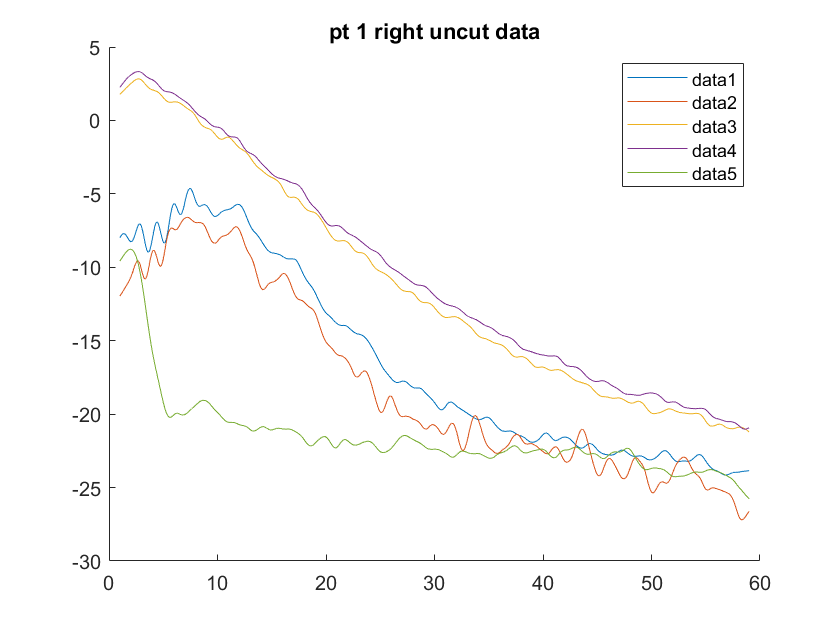

figure
for i = 1:5
    field = append("treatment", num2str(i));
    [outDAT] = proc1(data.(field).timeDomain); 
    %collect time domain data from given field in Data strcut I made 

    hold on
    plot(outDAT.freq,outDAT.pwr)
end
legend()
title("pt 1 right uncut data")

It's apparent that Treatments 3 and 4 are similar to each other but not the other data 

Look into raw data to see what's going on 

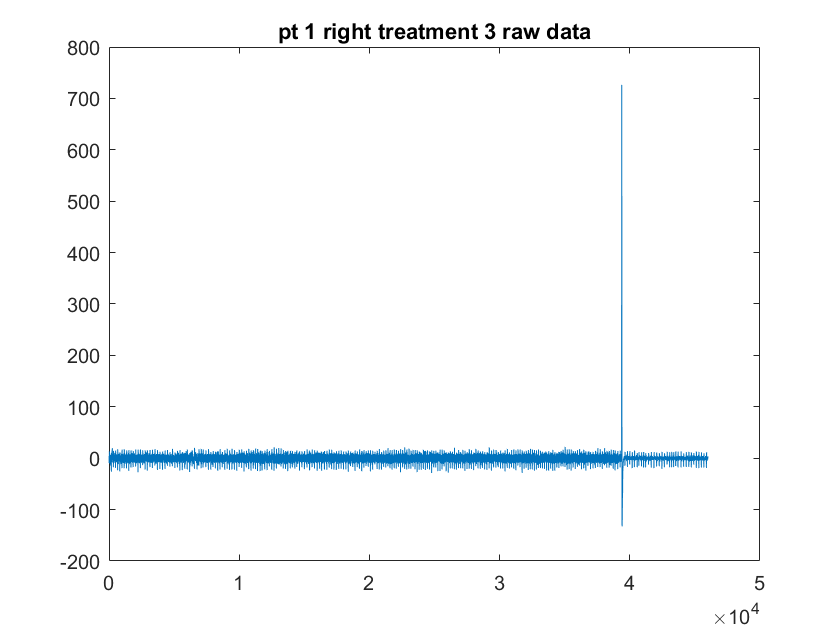

figure
field = append("treatment", num2str(3));
plot(data.(field).timeDomain)
title("pt 1 right treatment 3 raw data")

timeTotalT3 = length(data.(field).timeDomain)/250/60

timeTotalT3 = 3.0667

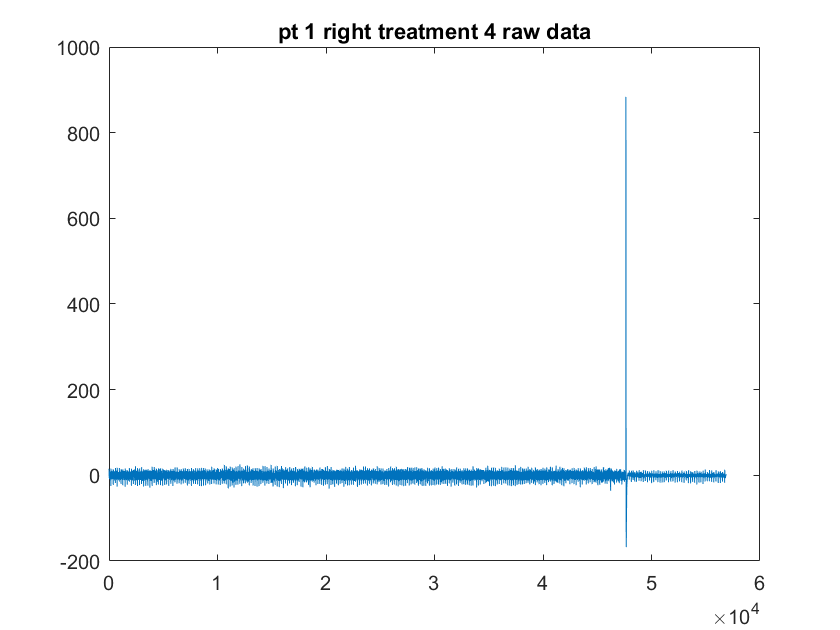


figure
field = append("treatment", num2str(4));
plot(data.(field).timeDomain)
title("pt 1 right treatment 4 raw data")

timeTotalT4 = length(data.(field).timeDomain)/250/60

timeTotalT4 = 3.7917

Using inspection, cut out the spike and replot treatments 3 and 4 with the other data 

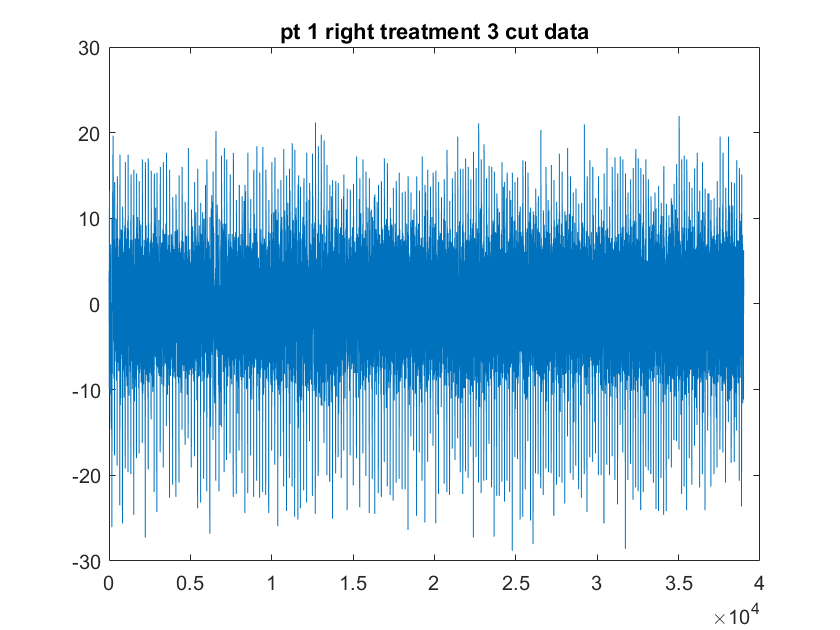

%treatement 3 cut at 3.9e4 
figure
field = append("treatment", num2str(3));
proc3 = data.(field).timeDomain(1:39000);
plot(proc3)
title("pt 1 right treatment 3 cut data")

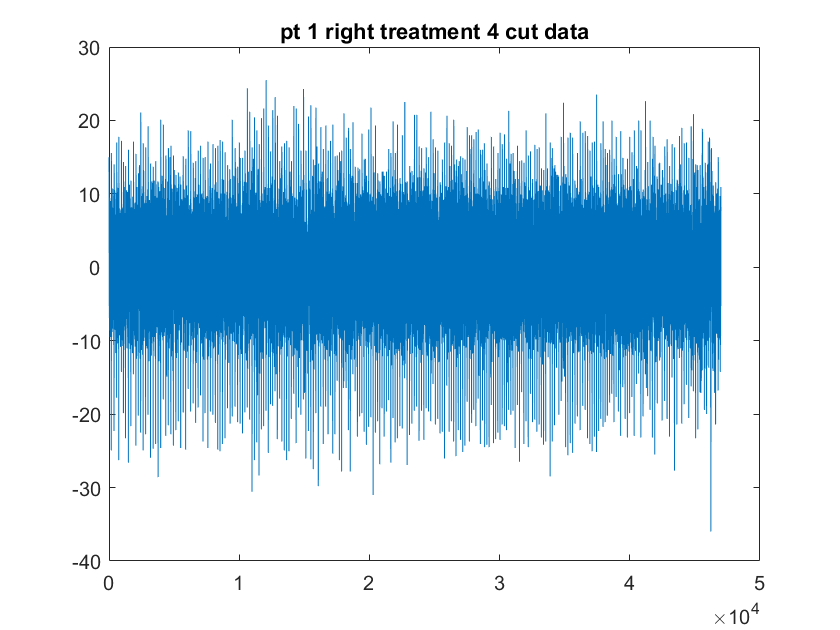


%treatement 4 cut at 4.7e4 
figure
field = append("treatment", num2str(4));
proc4 = data.(field).timeDomain(1:47000);
plot(proc4)
title("pt 1 right treatment 4 cut data")


data.treatment3.timeDomain = proc3; 
timeCutT3 = length(proc3)/250/60

timeCutT3 = 2.6000

data.treatment4.timeDomain = proc4; 
timeCutT4 = length(proc4)/250/60

timeCutT4 = 3.1333

Replot all data with each other now that the odd data is cut 

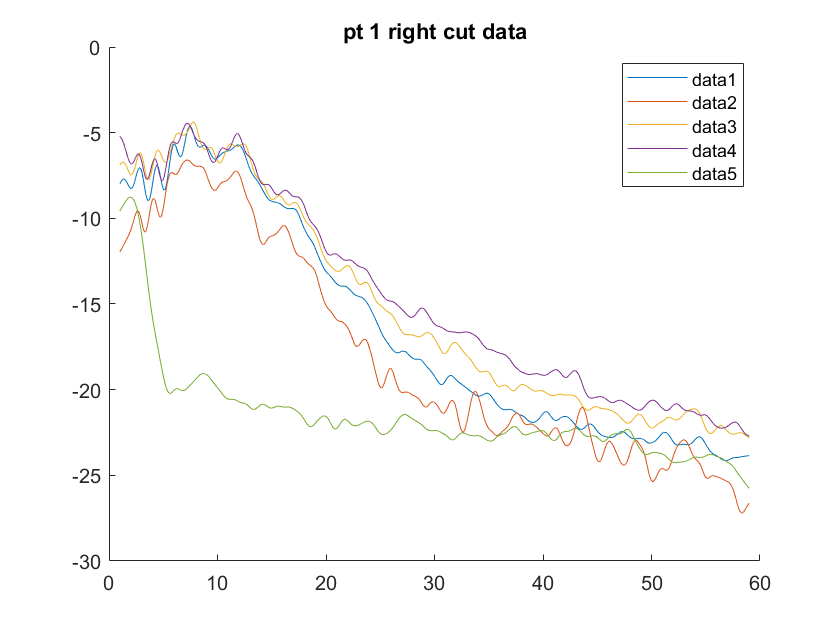

figure
for i = 1:5
    field = append("treatment", num2str(i));
    [outDAT] = proc1(data.(field).timeDomain); 
    %collect time domain data from given field in Data strcut I made 

    hold on
    plot(outDAT.freq,outDAT.pwr)
end
legend()
title("pt 1 right cut data")

function [outDAT] = proc1(dataIN)
%purpose of this fucntion is really to proces the data in a
%general and nonspecific way 

hp = highpass(dataIN,0.8,250);
lp = lowpass(hp,59,250);
%dont recall how these numbers were created 
[x,y] = pspectrum(lp,250,'FrequencyLimits',[1 59]);

xl = 10*log10(x);
%plots bode-ish of power from pspectrum
x2 = smoothdata(xl,'gaussian',150);
%smooth the bode 

outDAT.freq = y;
outDAT.pwr = x2;

end